# mAD 64 genes merge

## merge round 1 dots and rotate

% base_path = 'G:/2021-03-01-mAD-64genes-9919/'
% base_path = 'G:/2021-03-06-mAD-64genes-9930/'
% base_path = 'G:/2021-03-11-mAD-64genes-9721/'
base_path = 'G:/2021-03-15-mAD-64genes-9781/'

input_path = fullfile(base_path, 'output/max');
input_dim = [3072 3072 30 4];


data_dirs = dir(fullfile(input_path, "tile*"));
data_dirs = struct2table(data_dirs);
data_dirs = natsort(data_dirs.name);

Ndirs = numel(data_dirs);

rotation_degress = -90; 


upd = textprogressbar(Ndirs, 'updatestep', 1);

% Iterate through each position folder
for p=1:Ndirs
    
    curr_data_dir = data_dirs{p};
    
    % output path 
    curr_out_path = fullfile(input_path, "round1_merged_rotated");
    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
    
    curr_rd1_max_out_path = fullfile(input_path, "round1_max_rotated");
    if ~exist(curr_rd1_max_out_path, 'dir')
        mkdir(curr_rd1_max_out_path)
    end
    
    curr_path = fullfile(base_path, 'round1', curr_data_dir);
    curr_files = dir(fullfile(curr_path, "*.tif"));
    curr_img = zeros(input_dim, 'uint8');
    
    for i=1:4
        curr_file_path = fullfile(curr_path, curr_files(i).name);
        curr_img(:,:,:,i) = new_LoadMultipageTiff(curr_file_path, 'uint8', 'uint8', false);
    end
    
    curr_img = max(curr_img, [], 4);
    curr_img = imrotate(curr_img, rotation_degress); % rotate the image clockwise by 90 degrees
    curr_img = MinMax_uint8(curr_img);
    curr_max = max(curr_img, [], 3);
    curr_max = imadjust(curr_max);
    
    curr_fname = fullfile(curr_out_path, sprintf("%s.tif", curr_data_dir));
    if exist(curr_fname, 'file') == 2
        delete(curr_fname);
    end
    
    for j=1:input_dim(3)
        imwrite(curr_img(:,:,j), curr_fname, 'writemode', 'append');        
    end
    
    imwrite(curr_max, fullfile(curr_rd1_max_out_path, sprintf("%s.tif", curr_data_dir)));
    
%     % rotate round 1 dapi
%     curr_dapi_folder = fullfile(base_path, 'round1', curr_data_dir);
%     curr_files = dir(fullfile(curr_dapi_folder, "*.tif"));
%     curr_dapi_file = fullfile(curr_files(5).folder, curr_files(5).name);
%     curr_out_path = fullfile(input_path, "dapi_rotated");
%     if ~exist(curr_out_path, 'dir')
%         mkdir(curr_out_path)
%     end
%     
%     curr_max_out_path = fullfile(input_path, "dapi_max_rotated");
%     if ~exist(curr_max_out_path, 'dir')
%         mkdir(curr_max_out_path)
%     end
%     
%     
%     curr_img = new_LoadMultipageTiff(curr_dapi_file, 'uint8', 'uint8', false);
%     curr_img = imrotate(curr_img, rotation_degress); % rotate the image clockwise by 90 degrees
%     curr_img = MinMax_uint8(curr_img);
%     curr_max = max(curr_img, [], 3);
%     curr_max = imadjust(curr_max);
    
%     curr_fname = fullfile(curr_out_path, sprintf("%s.tif", curr_data_dir));
%     if exist(curr_fname, 'file') == 2
%         delete(curr_fname);
%     end
%     
%     for j=1:input_dim(3)
%         imwrite(curr_img(:,:,j), curr_fname, 'writemode', 'append');        
%     end
    
%     imwrite(curr_max, fullfile(curr_max_out_path, sprintf("%s.tif", curr_data_dir)));
%     
    upd(p);
end

## rotate merged dots, pi, tau, plaque

categories = ["Gfap", "pi", "plaque", "tau"];

for curr_category=categories
    curr_path = fullfile(input_path, curr_category);
    curr_files = dir(fullfile(curr_path, "*.tif"))
    % input_files = struct2table(input_files);
    % input_files = natsort(input_files.name);
    
    Nfiles = numel(curr_files);
    upd = textprogressbar(Ndirs, 'updatestep', 1);
    
    curr_out_path = fullfile(input_path, sprintf("%s_rotated", curr_category));
    if ~exist(curr_out_path, 'dir')
        mkdir(curr_out_path)
    end
    
    for p=1:Nfiles
        curr_file = fullfile(curr_path, curr_files(p).name);
        curr_img = new_LoadMultipageTiff(curr_file, 'uint8', 'uint8', false);
        curr_img = imrotate(curr_img, -90);
        
        curr_fname = fullfile(curr_out_path, curr_files(p).name);
        if exist(curr_fname, 'file') == 2
            delete(curr_fname);
        end
        
        for j=1:input_dim(3) 
            imwrite(curr_img(:,:,j), curr_fname, 'writemode', 'append');        
        end
        
        upd(p);
    end

end

## Stitch images with Fiji

% merge dots 
stitch_file = fullfile(input_path, "round1_merged_rotated/", "TileConfiguration.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y' 'z'};
TileConfiguration.x = int32(TileConfiguration.x);
TileConfiguration.y = int32(TileConfiguration.y);

head(TileConfiguration, 5)

ans = 5×4 table
    tile      x      y    z
    ____    _____    _    _

      1         0    0    0
      9      2764    0    0
     17      5528    0    0
     25      8292    0    0
     33     11056    0    0



%% Clear temporary variables
clear opts

%%%%
trim_range = 1:25;
%%%%

global_offsets = int32(abs([min(TileConfiguration.x); min(TileConfiguration.y)]));

% load stitched dapi image
dapi_file = fullfile(input_path, "stitched_images", 'pi.tif')

dapi_file = "G:\2021-03-15-mAD-64genes-9781\output\max\stitched_images\pi.tif"

dapi_img = imread_big(dapi_file);
dapi_max = max(dapi_img, [], 3);


merged_points = int32([]);
merged_reads = {};
merged_region = [];

for r=1:size(TileConfiguration,1)
% for r=1:40
    
    % get each row of tileconfig
    curr_row = table2cell(TileConfiguration(r, :));
    [tile, x, y, z] = curr_row{:};
    
    % load dots of each tile
    curr_position_dir = sprintf("tile_%d", tile)
    curr_dot_file = fullfile(input_path, curr_position_dir, "goodPoints_max3d.mat");
    load(curr_dot_file);
    
    if ~isempty(tile_goodReads)
         if rotation_degress == -90
            % rotate 90 c
            temp = tile_goodSpots;
            tile_goodSpots(:, 2) = temp(:, 1);
            tile_goodSpots(:, 1) = 3073 - temp(:, 2);
        elseif rotation_degress == -180
            % rotate 180 c
            temp = tile_goodSpots;
            tile_goodSpots(:, 1) = 3073 - temp(:, 1);
            tile_goodSpots(:, 2) = 3073 - temp(:, 2);
        end
        
        % trim along z
        toKeep = ismember(tile_goodSpots(:,3), trim_range);
        tile_goodSpots = tile_goodSpots(toKeep, :);
        tile_goodReads = tile_goodReads(toKeep);
        tile_goodSpots(:,3) = tile_goodSpots(:,3) - trim_range(1) + 1;
        
        % add offset
%         if x < 0
%             x = 0;
%         end

        tile_goodSpots = int32(tile_goodSpots) + int32([x y z]);
        tile_goodSpots(:, 1) = tile_goodSpots(:, 1) + global_offsets(1); 
        tile_goodSpots(:, 2) = tile_goodSpots(:, 2) + global_offsets(2); 
            
        % construct dots region
        current_min = min(tile_goodSpots, [], 1);
        current_max = max(tile_goodSpots, [], 1);
        if current_max(1) > size(dapi_max, 2)
            fprintf("1")
            current_max(1) = size(dapi_max, 2);
            toKeep = tile_goodSpots(:, 1) <= current_max(1);
            tile_goodSpots = tile_goodSpots(toKeep, :);
            tile_goodReads = tile_goodReads(toKeep);
        
        else if current_max(2) > size(dapi_max, 1)
                fprintf("2")
                current_max(2) = size(dapi_max, 1);   
             
                toKeep = tile_goodSpots(:, 2) <= current_max(2);
                tile_goodSpots = tile_goodSpots(toKeep, :);
                tile_goodReads = tile_goodReads(toKeep);
            
        end
        end
        current_region = zeros(size(dapi_max));
        current_region(current_min(2):current_max(2), current_min(1):current_max(1)) = 1;
        
        % merge dots 
        if isempty(merged_region)
            merged_region = current_region;
        else
            current_overlap = merged_region & current_region;
            merged_region = merged_region | current_region;
            current_region = current_region - current_overlap; 
            
            temp_cell = num2cell(tile_goodSpots, 2); 
            current_lindex = cellfun(@(x) sub2ind(size(dapi_img), x(2), x(1)), temp_cell);
            current_logical = logical(current_region(current_lindex));
            tile_goodSpots = tile_goodSpots(current_logical, :);
            tile_goodReads = tile_goodReads(current_logical);
        end
        
        % save current 
        merged_points = [merged_points; tile_goodSpots];
        merged_reads = [merged_reads; tile_goodReads];
    end
end

curr_position_dir = "tile_1"

curr_position_dir = "tile_9"

curr_position_dir = "tile_17"

curr_position_dir = "tile_25"

curr_position_dir = "tile_33"

curr_position_dir = "tile_41"

curr_position_dir = "tile_49"

curr_position_dir = "tile_57"

curr_position_dir = "tile_2"

curr_position_dir = "tile_10"

curr_position_dir = "tile_18"

curr_position_dir = "tile_26"

curr_position_dir = "tile_34"

curr_position_dir = "tile_42"

curr_position_dir = "tile_50"

curr_position_dir = "tile_58"

curr_position_dir = "tile_3"

curr_position_dir = "tile_11"

curr_position_dir = "tile_19"

curr_position_dir = "tile_27"

curr_position_dir = "tile_35"

curr_position_dir = "tile_43"

curr_position_dir = "tile_51"

curr_position_dir = "tile_59"

curr_position_dir = "tile_4"

curr_position_dir = "tile_12"

curr_position_dir = "tile_20"

curr_position_dir = "tile_28"

curr_position_dir = "tile_36"

curr_position_dir = "tile_44"

curr_position_dir = "tile_52"

curr_position_dir = "tile_60"

curr_position_dir = "tile_5"

curr_position_dir = "tile_13"

curr_position_dir = "tile_21"

curr_position_dir = "tile_29"

curr_position_dir = "tile_37"

curr_position_dir = "tile_45"

curr_position_dir = "tile_53"

curr_position_dir = "tile_61"

curr_position_dir = "tile_6"

curr_position_dir = "tile_14"

curr_position_dir = "tile_22"

curr_position_dir = "tile_30"

curr_position_dir = "tile_38"

curr_position_dir = "tile_46"

curr_position_dir = "tile_54"

curr_position_dir = "tile_62"

curr_position_dir = "tile_7"

curr_position_dir = "tile_15"

curr_position_dir = "tile_23"

curr_position_dir = "tile_31"

curr_position_dir = "tile_39"

curr_position_dir = "tile_47"

curr_position_dir = "tile_55"

curr_position_dir = "tile_63"

curr_position_dir = "tile_8"

curr_position_dir = "tile_16"

curr_position_dir = "tile_24"

curr_position_dir = "tile_32"

curr_position_dir = "tile_40"

curr_position_dir = "tile_48"

curr_position_dir = "tile_56"

curr_position_dir = "tile_64"

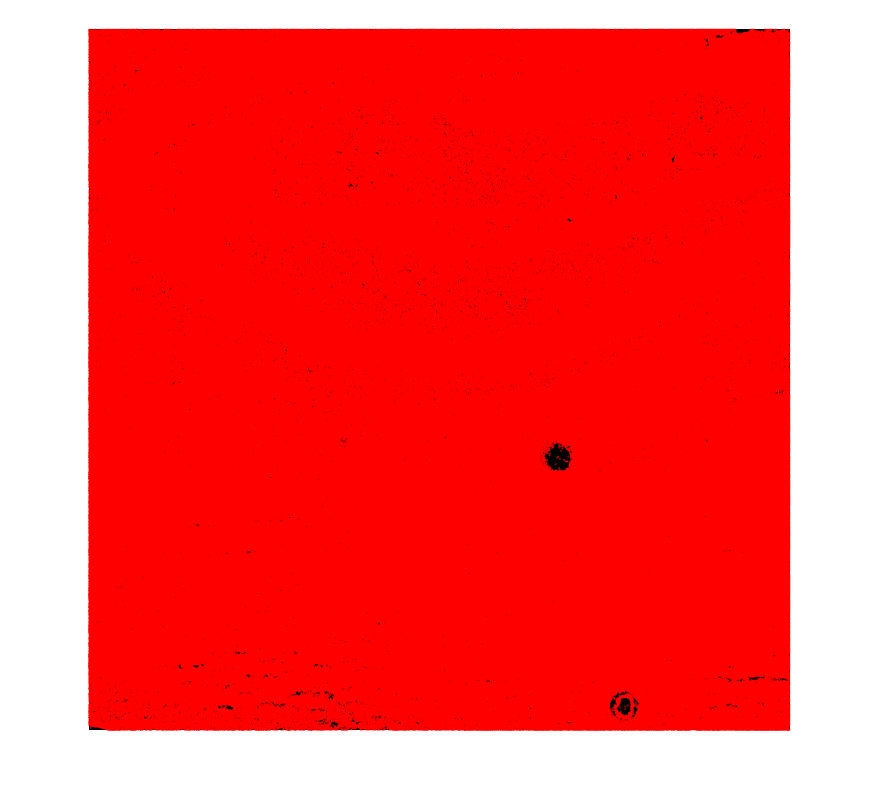


plot_centroids(merged_points, dapi_max, 1)

save(fullfile(input_path, 'merged_goodPoints_max3d_ztrimmed_1_25.mat'), "merged_points", "merged_reads");

## Plot reads for specific gene

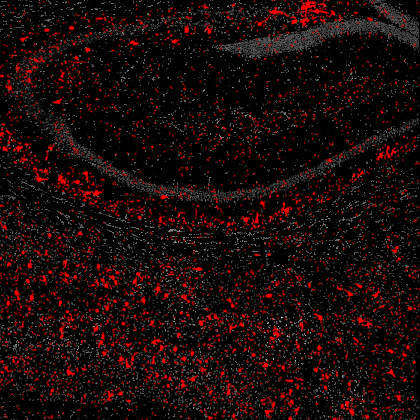

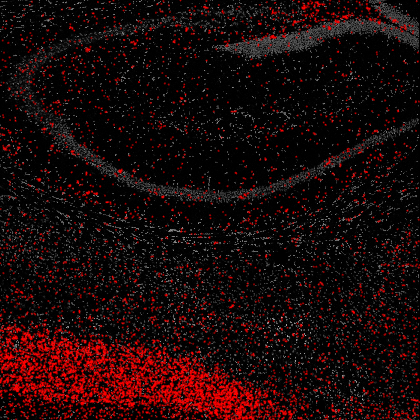

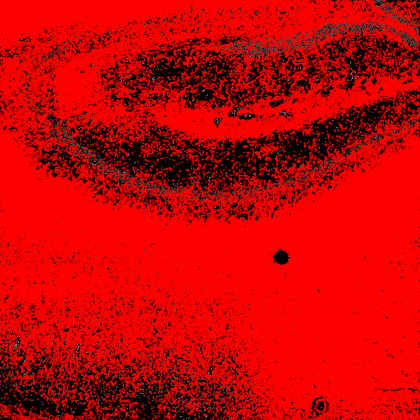

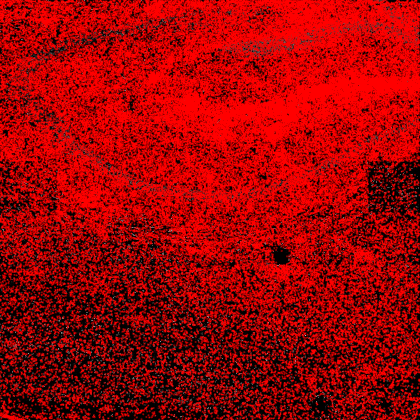

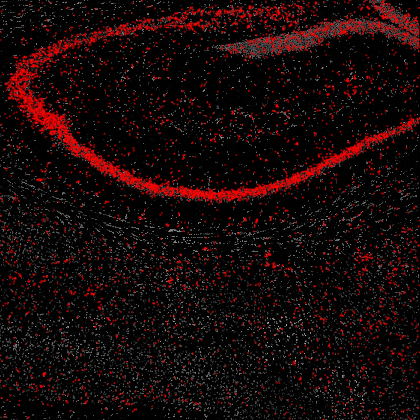

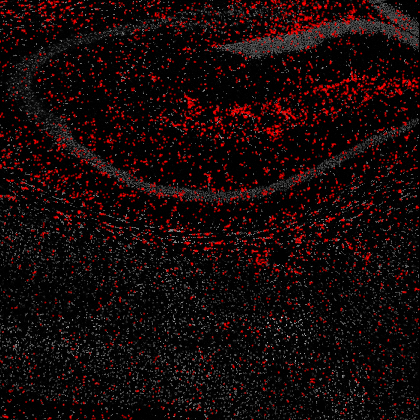

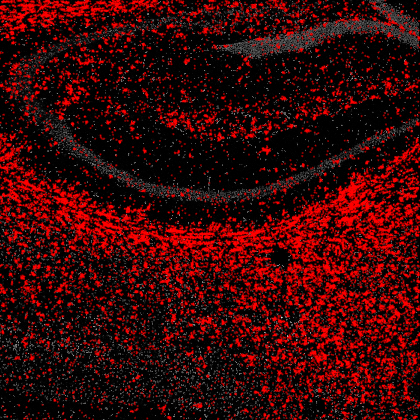

saveAS = true;
[ geneToSeq, seqToGene ] = new_LoadCodebook( base_path, [], true );
[C,ia,ic] = unique(merged_reads);
a_counts = accumarray(ic,1);
value_counts = table(C, a_counts);
value_counts = sortrows(value_counts, 'a_counts', 'descend');
genes = cellfun(@(x) seqToGene(x), value_counts.C, 'UniformOutput', false);
value_counts.genes = genes;
top5 = value_counts.genes(1:20);
curated = {"SLC17A7"; "CUX2"; "RORB"; "SULF2"; "PCP4"; "GAD1"; "PVALB"; "SST"; "MBP"; "MOBP"};
selected_genes = [top5; curated];

selected_genes = {'SST', 'CUX2', 'MBP', 'GFAP', 'SERPINA3N', 'C4B', 'PLP1'};
%  selected_genes = keys(geneToSeq);

for i=1:numel(selected_genes)
    gene = selected_genes{i};
    seq = geneToSeq(gene);
    good_points = ismember(merged_reads, seq);
    good_points = merged_points(good_points, :);
    
    nreads = value_counts(value_counts.genes == string(gene), :).a_counts;
    
    fh = figure; 
    ah = axes('Units','Normalize','Position', [0 0 1 1]);
    imshow(dapi_max)
    hold on
    plot(good_points(:,1), good_points(:,2), '.', "Color", 'red', "MarkerSize", 2)
    hold off
    axis(ah, 'square');
    fh.Position(3) = fh.Position(4);
%     camroll(180)
    
    if saveAS
        curr_out_path = fullfile(input_path, 'reads_pattern');
        if ~exist(curr_out_path, 'dir')
            mkdir(curr_out_path)
        end
        fig_name = fullfile(curr_out_path, sprintf("%d_%s_%s.png", i, gene, seq));
        saveas(gcf, fig_name)
    end
    
end

## Trim the image and dots

current_dataset = "trimmed_1_25"

current_dataset = "trimmed_1_25"

trim_range = 1:25;

% load pi
dapi_file = fullfile(input_path, "stitched_images", 'pi.tif');
[dapi_img, Nframes]= imread_big(dapi_file); 

% load round1
merged_dots_file = fullfile(input_path, "stitched_images", 'round1_merged.tif');
[merged_dots_img, Nframes]= imread_big(merged_dots_file); 

% load gfap
gfap_file = fullfile(input_path, "stitched_images", 'Gfap.tif');
[gfap_img, Nframes]= imread_big(gfap_file); 

% load plaque
plaque_file = fullfile(input_path, "stitched_images", 'plaque.tif');
[plaque_img, Nframes]= imread_big(plaque_file); 

% load tau
tau_file = fullfile(input_path, "stitched_images", 'tau.tif');
[tau_img, Nframes]= imread_big(tau_file); 

% load dots
load(fullfile(input_path, "merged_goodPoints_max3d_ztrimmed_1_25.mat"));
current_min = min(merged_points, [], 1)

current_min = 1×3 int32 row vector
    1   13    1


current_max = max(merged_points, [], 1)

current_max = 1×3 int32 row vector
   22407   22420      25


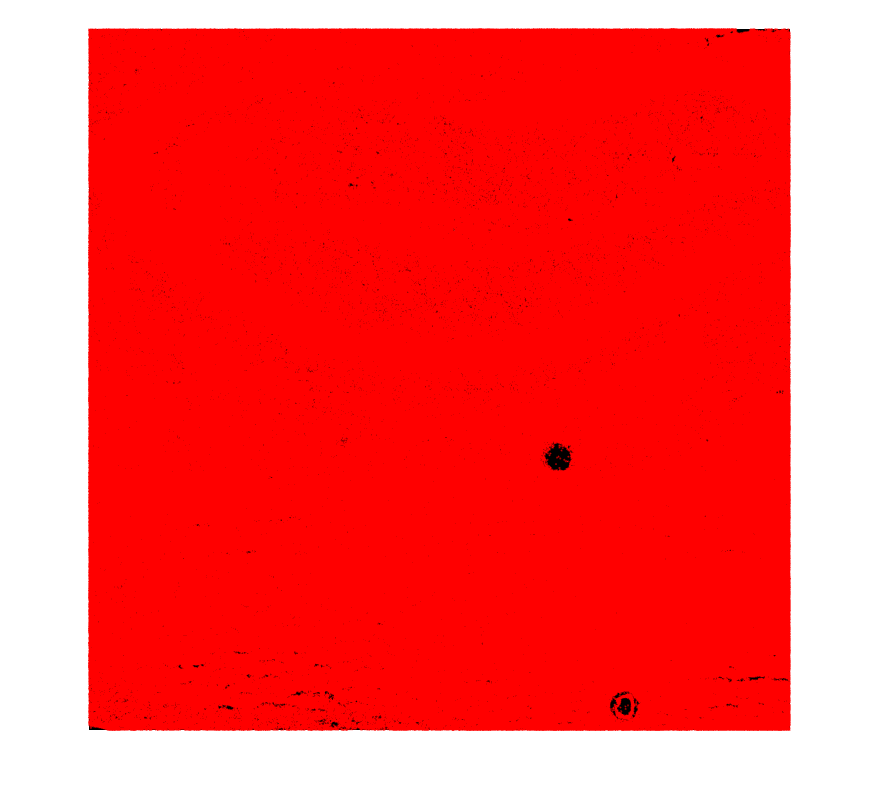


% trim image
dapi_img = dapi_img(current_min(2):current_max(2), current_min(1):current_max(1), trim_range(1):trim_range(end));
merged_dots_img = merged_dots_img(current_min(2):current_max(2), current_min(1):current_max(1), trim_range(1):trim_range(end));
gfap_img = gfap_img(current_min(2):current_max(2), current_min(1):current_max(1), trim_range(1):trim_range(end));
plaque_img = plaque_img(current_min(2):current_max(2), current_min(1):current_max(1), trim_range(1):trim_range(end));
tau_img = tau_img(current_min(2):current_max(2), current_min(1):current_max(1), trim_range(1):trim_range(end));

% trim dots
merged_points(:,1) = merged_points(:,1) - current_min(1) + 1;
merged_points(:,2) = merged_points(:,2) - current_min(2) + 1;

dapi_max = max(dapi_img, [], 3);
plot_centroids(merged_points, dapi_max, 2)


% save images 
curr_out_path = fullfile(input_path, "reads_assignment", current_dataset);
if ~exist(curr_out_path, 'dir')
    mkdir(curr_out_path)
end

curr_fname = fullfile(curr_out_path, 'pi.tif');
dapi_img = max(dapi_img, [], 3);
SaveSingleTiff(dapi_img, curr_fname)

curr_fname = fullfile(curr_out_path, 'merged_dots.tif');
merged_dots_img = max(merged_dots_img, [], 3);
SaveSingleTiff(merged_dots_img, curr_fname)

curr_fname = fullfile(curr_out_path, 'Gfap.tif');
gfap_img = max(gfap_img, [], 3);
SaveSingleTiff(gfap_img, curr_fname)

curr_fname = fullfile(curr_out_path, 'plaque.tif');
plaque_img = max(plaque_img, [], 3);
SaveSingleTiff(plaque_img, curr_fname)

curr_fname = fullfile(curr_out_path, 'tau.tif');
tau_img = max(tau_img, [], 3);
SaveSingleTiff(tau_img, curr_fname)

save(fullfile(curr_out_path, sprintf("%s.mat", current_dataset)), "merged_points", "merged_reads");

keys(geneToSeq)

ans = 1×64 cell array
    {'ALDOC'}    {'AP2B1'}    {'APOE'}    {'AQP4'}    {'BRINP1'}    {'BSG'}    {'C1QA'}    {'C1QL3'}    {'C4B'}    {'CACNG4'}    {'CALM1'}    {'CAMK4'}    {'CCNB2'}    {'CD63'}    {'CD83'}    {'CD9'}    {'CDKN1A'}    {'CLDN11'}    {'CLEC7A'}    {'CNR1'}    {'CPLX1'}    {'CST3'}    {'CST7'}    {'CTSB'}    {'CTSL'}    {'CTSS'}    {'CUX2'}    {'DDIT3'}    {'FLT1'}    {'GABRA1'}    {'GAD1'}    {'GFAP'}    {'GPM6A'}    {'GPR17'}    {'GPR34'}    {'GRIN2B'}    {'HTRA1'}    {'KLK6'}    {'LAMP5'}    {'MBP'}    {'MYH11'}    {'MYO5A'}    {'NPY'}    {'P2RY12'}    {'PCDH9'}    {'PCP4'}    {'PDGFRA'}    {'PLP1'}    {'PRKCE'}    {'PVALB'}    {'RHOC'}    {'RPH3A'}    {'SERPINA3N'}    {'SLC17A7'}    {'SRRM2'}    {'SST'}    {'TGFBR1'}    {'TMSB4X'}    {'TREM2'}    {'TSHZ2'}    {'TSPAN7'}    {'VIM'}    {'VIP'}    {'VTN'}


values(geneToSeq)

ans = 1×64 cell array
    {'2112'}    {'2121'}    {'2134'}    {'2143'}    {'2222'}    {'2211'}    {'2244'}    {'2233'}    {'2332'}    {'2341'}    {'2314'}    {'2323'}    {'2442'}    {'2431'}    {'2424'}    {'2413'}    {'1212'}    {'1221'}    {'1234'}    {'1243'}    {'1122'}    {'1111'}    {'1144'}    {'1133'}    {'1432'}    {'1441'}    {'1414'}    {'1423'}    {'1342'}    {'1331'}    {'1324'}    {'1313'}    {'4312'}    {'4321'}    {'4334'}    {'4343'}    {'4422'}    {'4411'}    {'4444'}    {'4433'}    {'4132'}    {'4141'}    {'4114'}    {'4123'}    {'4242'}    {'4231'}    {'4224'}    {'4213'}    {'3412'}    {'3421'}    {'3434'}    {'3443'}    {'3322'}    {'3311'}    {'3344'}    {'3333'}    {'3232'}    {'3241'}    {'3214'}    {'3223'}    {'3142'}    {'3131'}    {'3124'}    {'3113'}
